# MATLABの機械学習手法による大手掲示板サービスRedditにて

# 投稿された政治的コメントの分類

### 所属クラス：C3, 氏名：山野 元久, 学籍番号：s1320112

## 1. 導入(Introduction)

　世界最大規模の匿名掲示板であるReddit。その中では度々政治的な議論が白熱する。今回得たデータセットでは、約13000個の投稿を保守的かリベラル的かに分類し、まとめている。ダウンロードしたデータセットを機械学習手法に通すことで、任意のテキストが与えられたときにそれが保守的かリベラル的かという判定を行うプログラムの開発、またどのような記述がそのように判定される要因になるのかについて分析したい。

## 2. データ(Data)

　この研究のために用いたデータセット"Liberals vs Conservatives on Reddit [13000 posts]"の詳細は以下の通りである。

- 名前：Liberals vs Conservatives on Reddit [13000 posts]

- 制作者：`Neel Gajare`

- データ取得元URL：https://www.kaggle.com/datasets/neelgajare/liberals-vs-conservatives-on-reddit-13000-posts/data

- 収集日：2022/3/3

- ライセンス：記載なし（説明欄にてFeel free to perform NLP models or anything elseのみ書かれている）

- サイト名：kaggle

- ファイル形式：CSV

各列の概要：

- Title：立てられたスレッドの題名

- Political Lean：リベラル的か右派的かの判別が書かれている。セルに直接"Liberal"あるいは"Conservative"と書かれている。

- Score：その投稿がどれだけ他のユーザーに指示されたかを示す評価数値。

- Id：投稿対し一意に割り当てられた識別子。Reddit側のシステムで付けられている。

- SubReddit：スレッドがどのサブレディット内で立てられたかを書いている。

- URL：スレッドのURL。

- Num of Comments：スレッドに対して寄せられたコメントの数。

- Text：スレッドの本文。（基本的には無い。）

- Date Created：スレッドが立てられた日付。

## 3. 手法(Method)

　3段階に分けてデータの分析を行う。まず、初めにグラフ等を用いてデータの可視化を行う。その次に、分類学習器アプリを用いてモデルの構築のための前処理を行う。最後にモデルの学習とその性能評価を行う。

#### 　3.1. データの可視化

　最初の手順として、readtable関数を用いて、今回のデータ"file_name.csv"をインポートする。

clf;
clear;
dataset = readtable("file_name.csv", "VariableNamingRule", "preserve");
dataset.Properties.VariableNames;

　ここで、例として最初のスレッドのタイトルと政治的な立ち位置を出力してみる。

disp(dataset(1,1))

                                                                                                         Title                                                                                                     
    _______________________________________________________________________________________________________________________________________________________________________________________________________________

    {'No matter who someone is, how they look like, what language they speak, what they wear, remember the human. For the sake of humanity, the working class can and must unite across all arbitrary boundaries.'}



disp(dataset(1,2))

    Political Lean
    ______________

     {'Liberal'}  



また、保守、リベラル、それぞれの意見がどれ程の割合でこのデータセットに入っているのかも調べる。

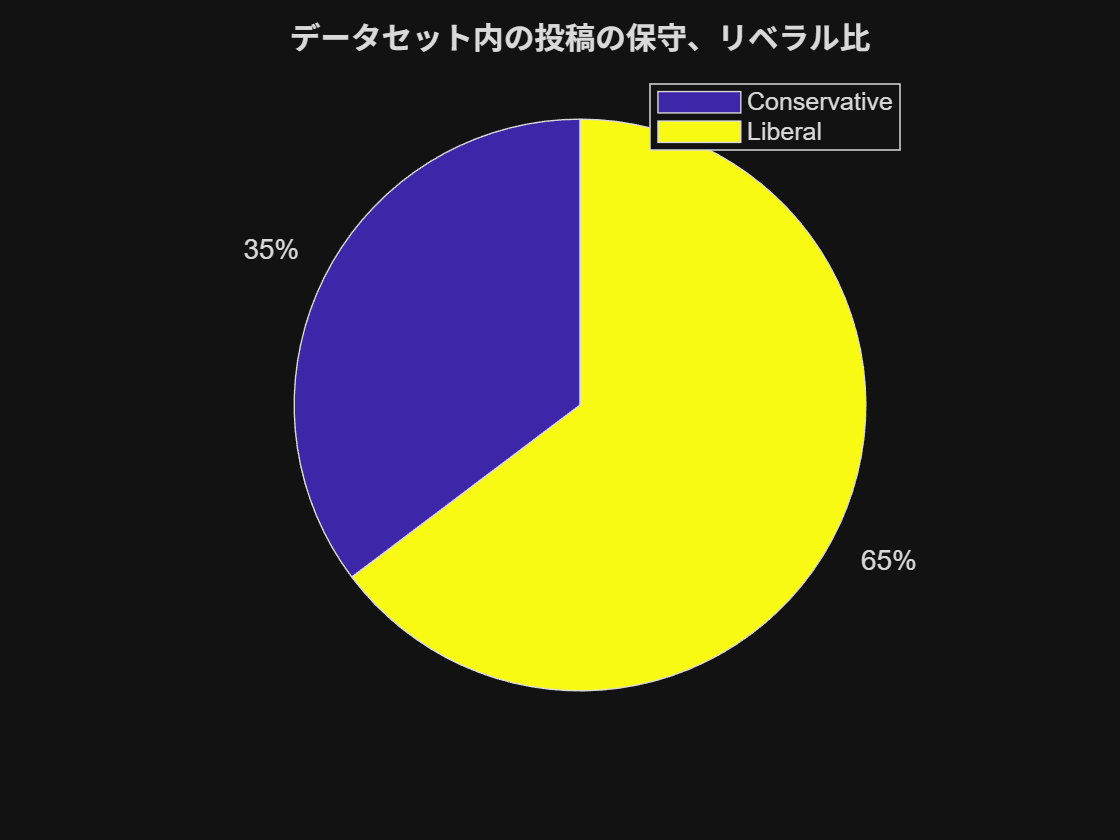

right_idx = nnz(dataset{:,2} == "Conservative");
left_idx = nnz(dataset{:,2} == "Liberal");
labels = ["Conservative", "Liberal"];

figure;
pie([right_idx, left_idx]);
title("データセット内の投稿の保守、リベラル比");
legend(labels);

　次に、投稿に対する評価であるScoreと、その投稿に付けられたコメント数であるNum of Commentsについて観察する。それぞれに対し、ボックスチャートを用いて全体の分布を見てみる。

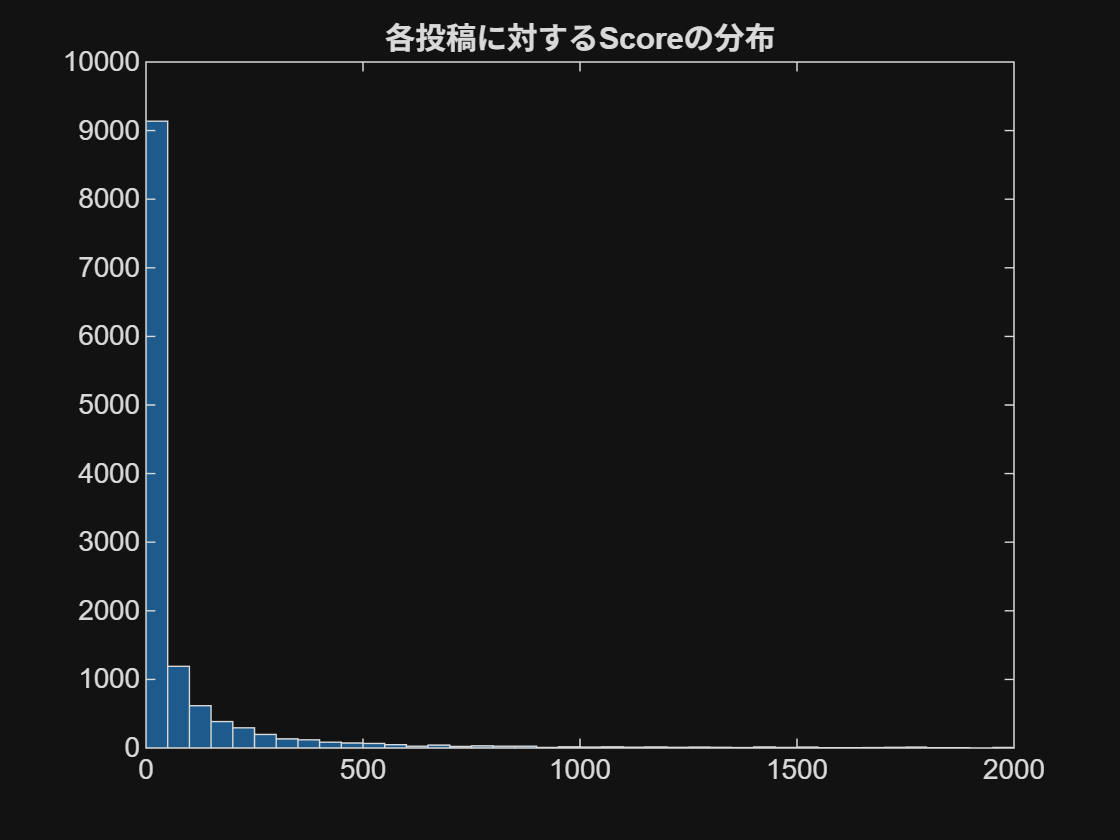

score = dataset(:,3).Variables;
comments = dataset(:,7).Variables;

figure;
histogram(score);
title("各投稿に対するScoreの分布");
xlim([0 2000]);

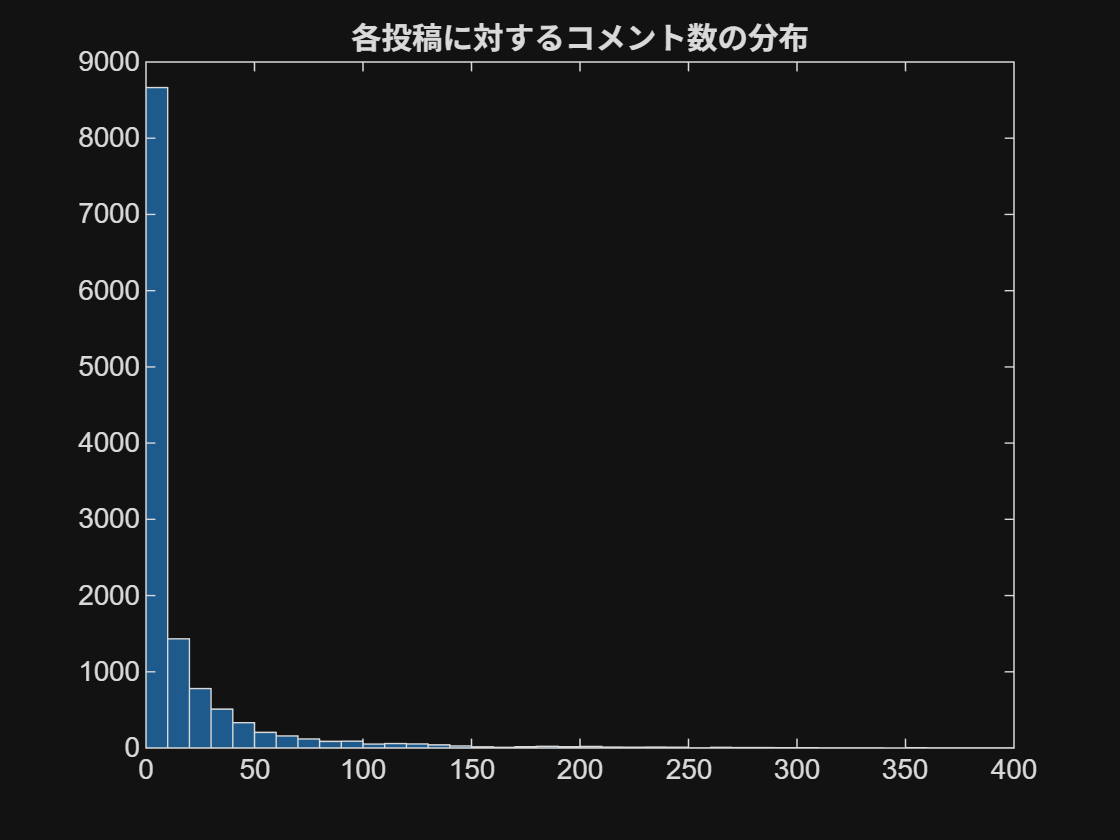

histogram(comments);
title("各投稿に対するコメント数の分布");
xlim([0 400]);

　次に、これらの投稿がどこのサブレディットにて発見されたものなのかをみてみる。

subreddit = dataset(:,5);
subreddit_name = unique(subreddit);
disp(subreddit_name);

           Subreddit       
    _______________________

    {'Capitalism'         }
    {'Communist'          }
    {'DemocraticSocialism'}
    {'Liberal'            }
    {'Libertarian'        }
    {'RadicalFeminism'    }
    {'SocialDemocracy'    }
    {'alltheleft'         }
    {'anarchocapitalism'  }
    {'conservatives'      }
    {'democrats'          }
    {'feminisms'          }
    {'progressive'        }
    {'republicans'        }
    {'socialism'          }



#### 3.2. 前処理

　データの概要を把握した所で、タイトルや本文から、保守的なコメントか、リベラル的なコメントかを判別できるような機械学習モデルを構築したい。その為に、まず、取り扱う対象となるデータをまとめ、コンピュータが取り扱いやすいようにトークン化をはじめとした前処理行う。行ったものをワードクラウドとして表示しみてみる。

Title = dataset{:,1};
Labels = dataset{:,2};

prepro_title = tokenizedDocument(Title);

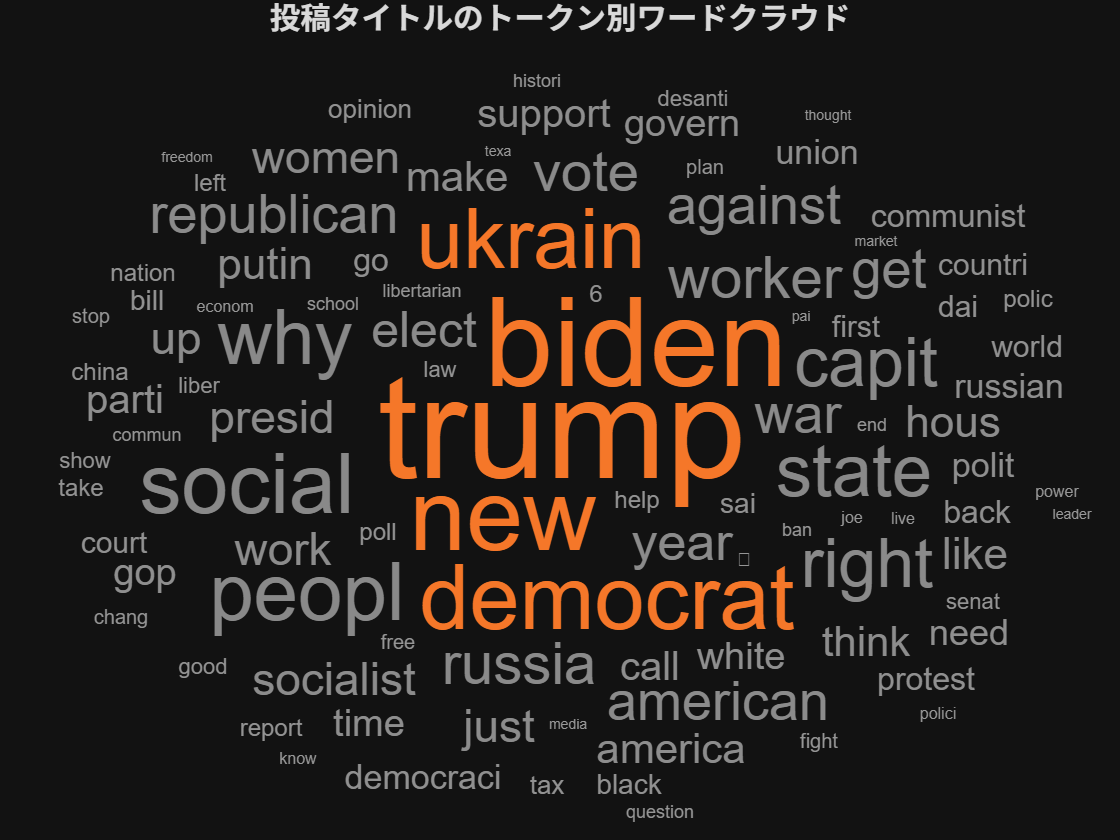

prepro_title = lower(prepro_title);
prepro_title = erasePunctuation(prepro_title);
prepro_title = removeStopWords(prepro_title);
prepro_title = normalizeWords(prepro_title);

figure;
wordcloud(prepro_title);
title("投稿タイトルのトークン別ワードクラウド");

　次に処理を終えたデータを数値化する。具体的には、Bag-of-Wordsとtfidfを用いて、最終的に単語頻度-逆文書頻度(tf-idf)行列を作成する。これによって誕生する行列は『投稿の数*投稿に登場する全単語』という巨大な行列であり、その各要素には、任意の投稿における任意の単語の重要度がdouble型で保管されている。

　さらに、matrix_titleとLabelsを訓練用と検証用に8:2で分割しておく。

bag_title = bagOfWords(prepro_title);
matrix_title = tfidf(bag_title);

cv = cvpartition(length(Labels),"HoldOut", 0.2);
trainIdx = cv.training;
testIdx = cv.test;

train_matrix = matrix_title(trainIdx, :);
train_labels = Labels(trainIdx);
test_matrix = matrix_title(testIdx, :);
test_labels = Labels(testIdx);

#### 3.3. スレッドタイトルの学習と分析

　ここから、様々な学習方法を用いて、その性能を検証する。今回はSVM、ランダムツリー、ロジスティック回帰によって学習を試みる。

　まず初めに、SVM（サポートベクタマシン）を使う。

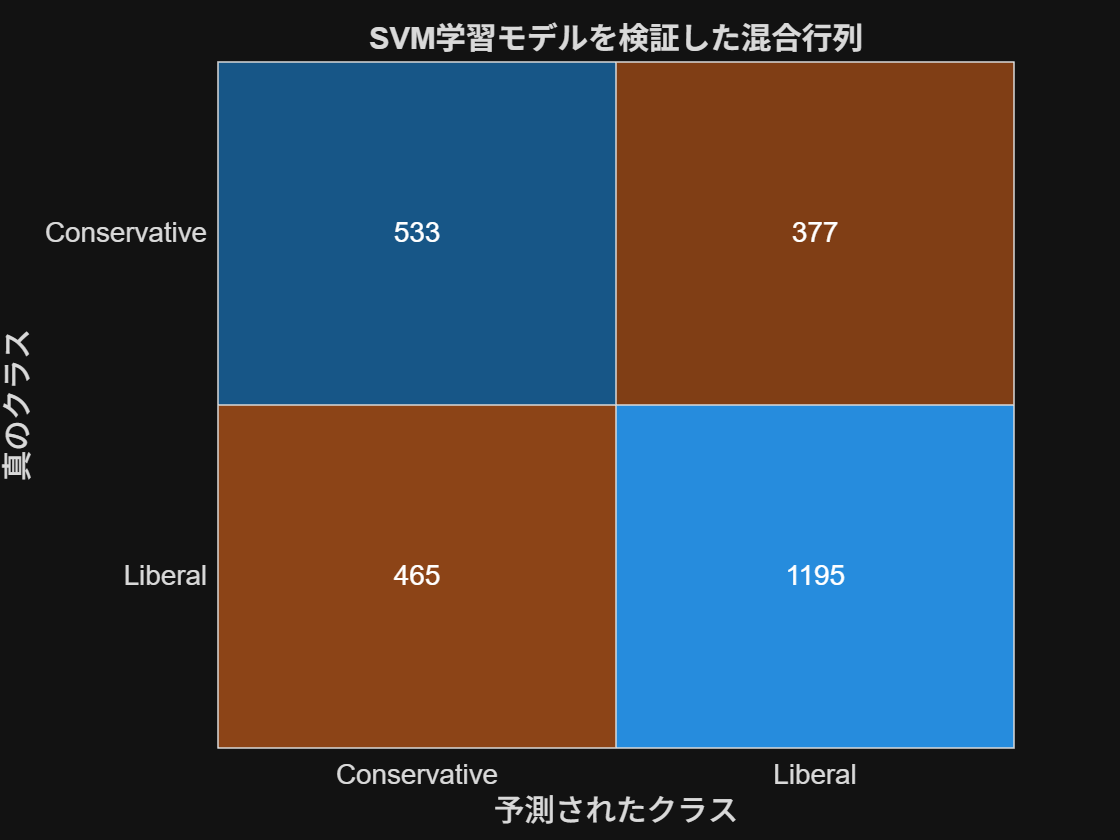

model_svm = fitcsvm(full(train_matrix), train_labels);
pred_svm = predict(model_svm, full(test_matrix));
figure;
confusionchart(test_labels, pred_svm);
title("SVM学習モデルを検証した混合行列");

　次に、ランダムツリーによるモデルを構築する。

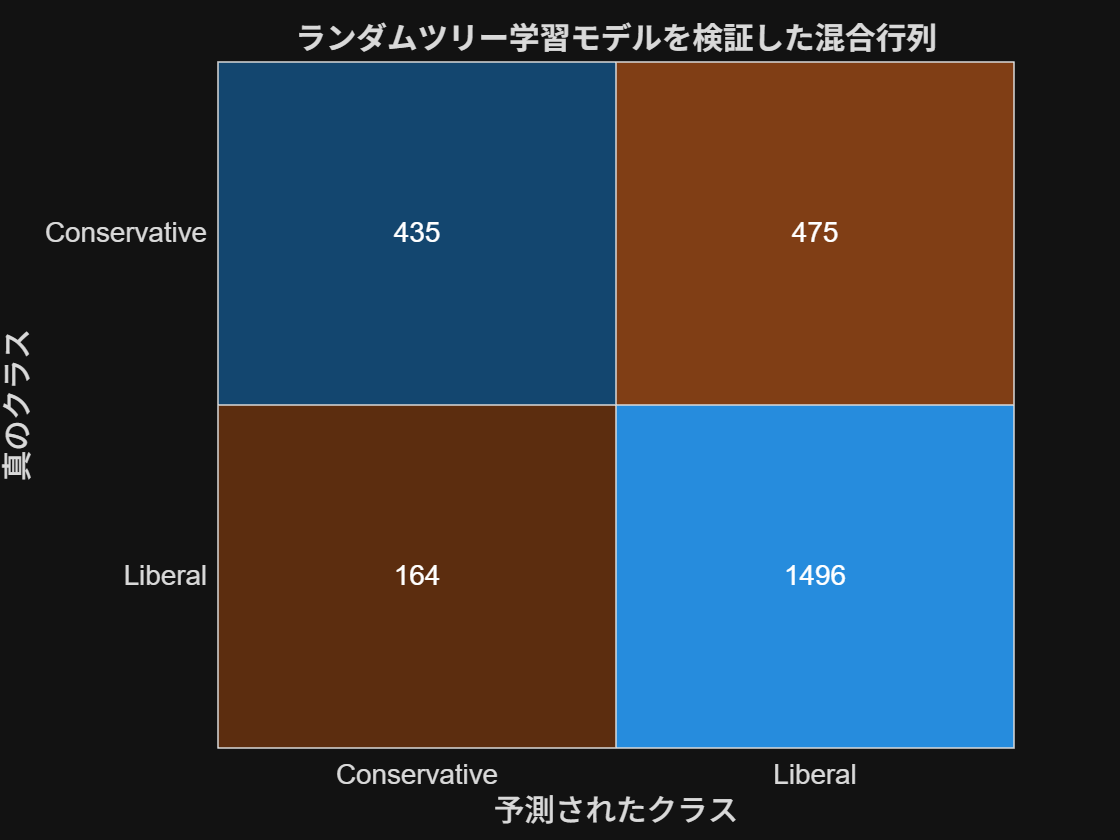

model_tree = fitcensemble(full(train_matrix), train_labels);
pred_tree = predict(model_tree, full(test_matrix));
figure;
confusionchart(test_labels, pred_tree);
title("ランダムツリー学習モデルを検証した混合行列");

最後に、回帰ロジスティックによるモデルを構築する。

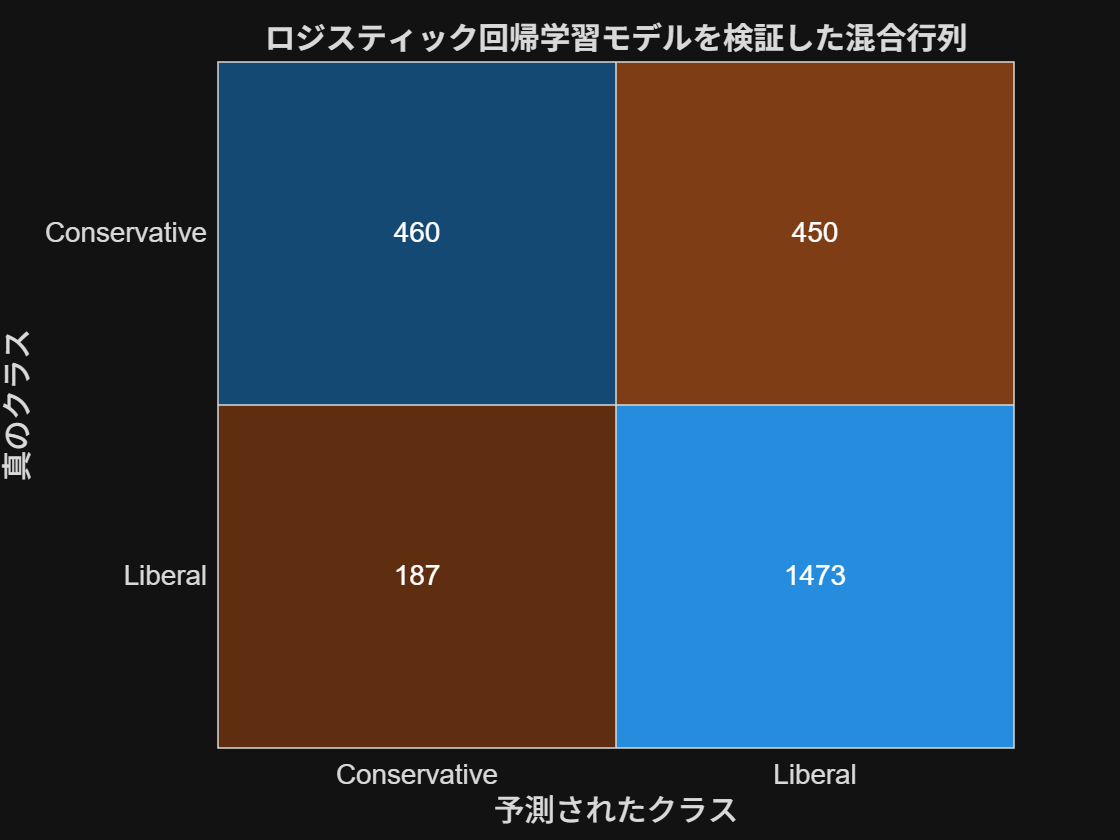

model_log = fitclinear(full(train_matrix), train_labels, 'Learner','logistic');
pred_log = predict(model_log, full(test_matrix));
figure;
confusionchart(test_labels, pred_log);
title("ロジスティック回帰学習モデルを検証した混合行列");

% Calculate accuracy for each model
ac_svm = sum(string(pred_svm) == string(test_labels)) / length(test_labels);
ac_tree = sum(string(pred_tree) == string(test_labels)) / length(test_labels);
ac_log = sum(string(pred_log) == string(test_labels)) / length(test_labels);

%各モデルの正答率
disp("Accuracy of SVM model:" + ac_svm);

Accuracy of SVM model:0.67237


disp("Accuracy of Random Tree model:" + ac_tree);

Accuracy of Random Tree model:0.75136


disp("Accuracy of Logistic model:" + ac_log);

Accuracy of Logistic model:0.75214


　それぞれのモデルにおいて、どの単語が重要だったかを分析するためにmodel.Betaから重みを分析して最も重要な単語の上位3位を表示させてみる。

[~,idx_svm] = sort(abs(model_svm.Beta), 'descend');
imp_tree = predictorImportance(model_tree);
[~,idx_tree] = sort(imp_tree, 'descend');
[~,idx_log] = sort(abs(model_log.Beta), 'descend');

wlist_svm = bag_title.Vocabulary(idx_svm(1:3));
wlist_tree = bag_title.Vocabulary(idx_tree(1:3));
wlist_log = bag_title.Vocabulary(idx_log(1:3));

% 各学習方法における上位3位の単語を表示
disp("SVM model:" + wlist_svm);

    "SVM model:uh"    "SVM model:reviv"    "SVM model:oldest"



disp("Random Tree model:" + wlist_tree);

    "Random Tree model:libertarian"    "Random Tree model:ukrain"    "Random Tree model:desanti"



disp("Logistic model:" + wlist_log);

    "Logistic model:libertarian"    "Logistic model:desanti"    "Logistic model:capit"



## 4. 結果(Result)

　3.手法(Method)より得られたグラフや学習結果等をまとめる。

　3.1.にて最初に求めた円グラフによると、データセット全体の投稿は65%がリベラル的であり、残り35％が保守的なものであることがわかった。

　また、ScoreとNum of Commentsがどのように分布するかについてヒストグラムによって可視化した。Scoreにおいては、評価約0が最も多く、より高い評価の数になるほど、対数的に減少する。同様に、Num of Commentsについても大半の投稿においては約0件程であり、より多いコメント数を残す投稿の総数は対数的に減少する。

　投稿元のサブレディットは全部で、15個存在する。それぞれ日本語にすると、｛資本主義, 共産主義, 民主社会主義, リベラル, 完全自由主義者, 急進的女性主義...といった意味を持つ。

　3.2.において、前処理したトークンを元に作成したワードクラウドでは、現米国大統領トランプ氏と元大統領バイデン氏の名前が最も顕著である。その他にも、ウクライナ(ukrain)や民主主義(democrat)という単語も目立っている。小さく散在している周辺の単語にはgetやshowといった英語で使われる一般的な単語の他に、社会主義者(socialist)や共和国？(republican)といった単語もみることができる。

　投稿タイトルを元に保守的かリベラルかを判定する機械学習モデルを3つ構築した。それぞれ、SVM、ランダムツリー、ロジスティック回帰のアルゴリズムに基づいている。全体の傾向として、全てのモデルはリベラル的な投稿を保守的なものを間違える事よりも、保守的な投稿をリベラルなものと誤答するパターンの方が多かった。得られた混合行列を見ると、全ての結果を通して保守的な投稿に対する予測の精度は約半分である。

　SVMによって作られたmodel_svmは3つのモデルの中で最も精度が低く、約68%であった。ただし、3つの中では保守的な投稿に対する精度が最も高い。（正答数581に対し誤答数345）

　ランダムツリーは、3つのモデルの中では中間の精度である。リベラル的な投稿に対する精度は極めて高く、正答数は1508に対して誤答数は136である。一方で、保守的な投稿に対する精度が低く、精度が50%を下回ってしまう。(正答数432に対して誤答数494)。

　ロジスティック回帰によって作られたモデルは、3つの中で最も精度が高く、約77%であった。結果はランダムツリーと近しいが、このmodel_logの場合は保守的な投稿を与えられた際の精度が50%を上回っている。

　SVMが重要と判断したトークン「ya, ronald, expos」は専らそのままだと英語としてはあまり意味の通っていないものであり、特に政治的な用語とも結びつかないものだった。（ただし、恐らくronaldは人名の可能性がある。）一方でランダムツリー内で重要とされたトークン「libetarian, ukrain, desanti」は上位二つは完全自由主義者とウクライナを意味しており、英語として意味の通う単語である。ロジスティック回帰では、「libetarian, desanti, women」がそれぞれ重要なトークンであることがわかった。womenを除く二つはランダムツリーとも共通している。

## 5. 議論/考察(Discuss)

　学習したモデルにおいて、このような結果が得られた要因について考察したい。3つのモデルは総じて、保守的な投稿に対する分析力に欠けていた。この原因は、データセットが持つ偏りであると推測する。結果より、データセットにある投稿の65%はリベラル的で残り35%が保守的であるため、特定のアルゴリズムに基づいて学習させた際に、リベラル的な投稿の特徴を多く受け取ってしまいモデルが不均衡になった事が原因として挙げられる。

　また、今回のNLP(自然言語処理)においては、単語の出現率と重要度のみによって傾向を判別しており、文脈や難解なスラング等の表現に対し適切な処理が出来なかった。これは、BERTを用いた、深層学習によって対応させることで更なる精度向上が期待できる。

　また、3つのモデルの内、ランダムツリーとロジスティック回帰は似たモデルを構築した。これは、短いタイトル文において各単語の持つ意味合いが必然的に大きくなり、用法も限定的になったため、非線形のランダムツリーが線形のロジスティック回帰と同じような分析をしたものだと考えた。

## 6. 結論(Conclusion)

　以上よりRedditの投稿タイトルからそれが保守的かリベラル的かを判別する機械学習モデルを開発、分析した。判別において特に重要視されているトークンは、「libetarian, woman, desanti」といったものであった。また、より高精度なモデルを作るためにはモデルが判別するためにバランスの取れたデータセットを用意すべきということがわかった。